Are models using the parital maintenence reaction replacement method sensitive to the timestep length?

Analyze cheater-including models using a variety of timesteps, including enzyme decay, without cell death

data file: **competition/timestep_dat.mat** or **competition/timestep_dat_celldeath.mat**

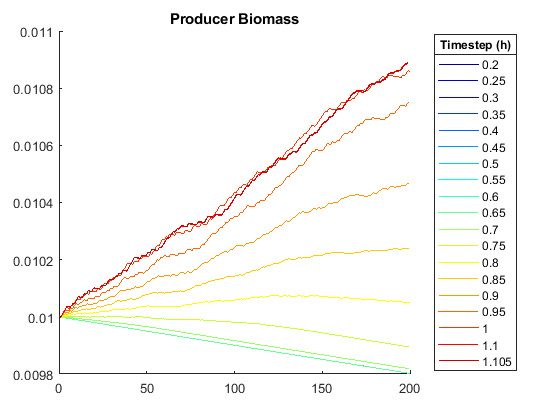

tdat = sortrows(tdat,'ts');
legendstr = arrayfun(@(x) num2str(x),tdat.ts,'uniformoutput',false);
[nrows, ncols] = size(tdat);
colors = jet(nrows);
figure();
hold on
for i = 1:nrows
    plot(tdat.t{i},tdat.biomass_producer{i},'color',colors(i,:));
end
title('Producer Biomass');
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep (h)');
hold off;

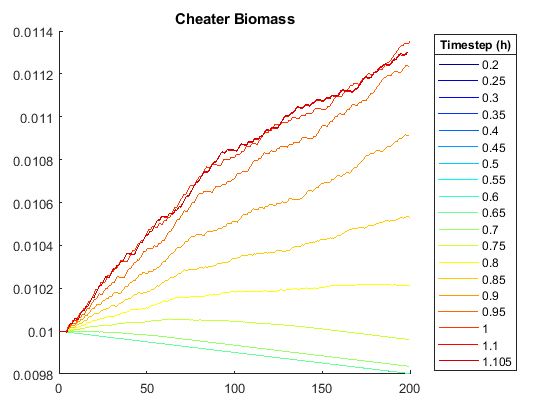


figure();
hold on
for i = 1:nrows
    plot(tdat.t{i},tdat.biomass_cheater{i},'color',colors(i,:));
end
title('Cheater Biomass');
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep (h)');
hold off;

Compare results using a different random seed

data file: **competition/random_seed.mat**

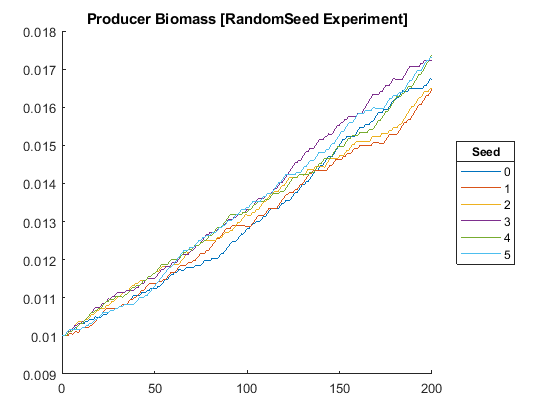

seeddat = sortrows(seeddat,'random_seed');
legendstr = arrayfun(@(x) num2str(x),seeddat.random_seed,'uniformoutput',false);
[nrows, ncols] = size(seeddat);
colors = lines(16);
figure();
hold on;
for i = 1:nrows
    plot(seeddat.t{i},seeddat.biomass_producer{i},'color',colors(i,:));
end
title('Producer Biomass [RandomSeed Experiment]');
leg = legend(legendstr,'location','eastoutside');
title(leg,'Seed');
hold off;

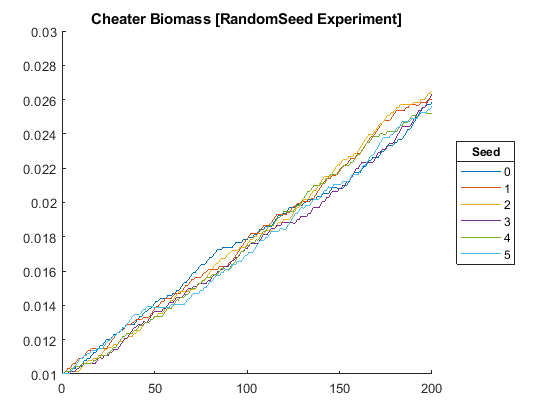

figure();
hold on;
for i = 1:nrows
    plot(seeddat.t{i},seeddat.biomass_cheater{i},'color',colors(i,:));
end
title('Cheater Biomass [RandomSeed Experiment]');
leg = legend(legendstr,'location','eastoutside');
title(leg,'Seed');
hold off;

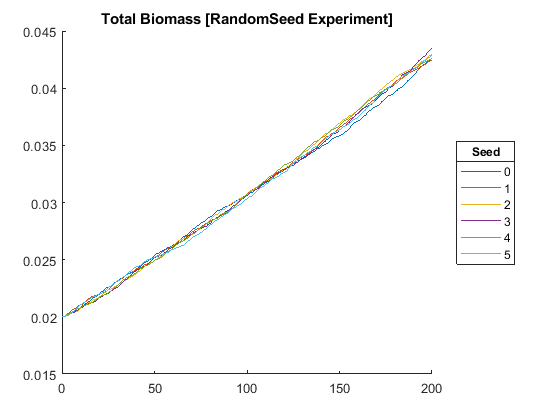


figure();
hold on;
for i = 1:nrows
    b = seeddat.biomass_producer{i} + seeddat.biomass_cheater{i};
    plot(seeddat.t{i},b,'color',colors(i,:));
end
title('Total Biomass [RandomSeed Experiment]');
leg = legend(legendstr,'location','eastoutside');
title(leg,'Seed');
hold off;

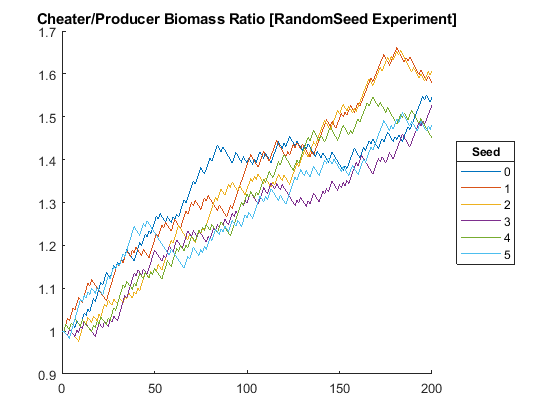


figure();
hold on;
for i = 1:nrows
    r = seeddat.biomass_cheater{i} ./ seeddat.biomass_producer{i};
    plot(seeddat.t{i},r,'color',colors(i,:));
end
title('Cheater/Producer Biomass Ratio [RandomSeed Experiment]');
leg = legend(legendstr,'location','eastoutside');
title(leg,'Seed');
hold off;

Run multiple times with different random seeds and timestep lengths

uses the data file **competition/random_dat.mat**

- Do results converge at a smaller timestep?

- Do the means of larger timesteps perform better?

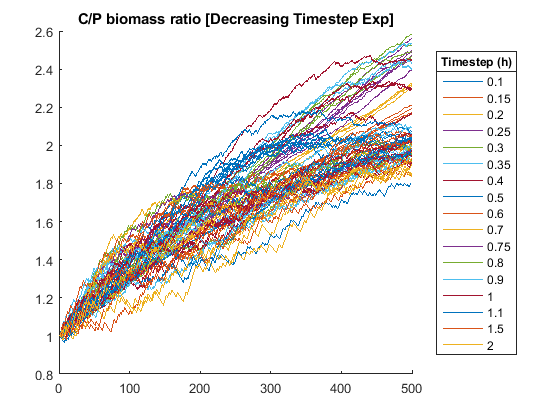

%plot the biomass ratios
colors = jet(20);
rd = sortrows(randdat,'ts');
rd = rd(~rd.maint_replaced,:);
timesteps = unique(rd.ts);
legendstr = unique(arrayfun(@(x) num2str(x),rd.ts,'uniformoutput',false))';
[nrows, ncols] = size(rd);

figure();
hold on;
lastts = 0;
for i = 1:nrows
    row = rd(i,:);
    coloridx = find(timesteps == row.ts(1));
    visibility = 'off';
    if coloridx > lastts
        lastts = coloridx;
        visibility = 'on';
    end
    r = row.biomass_cheater{1} ./ row.biomass_producer{1};
    plot(row.t{1},r,'color',colors(coloridx,:),'HandleVisibility',visibility);
end
title('C/P biomass ratio [Decreasing Timestep Exp]');
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep (h)');
hold off;

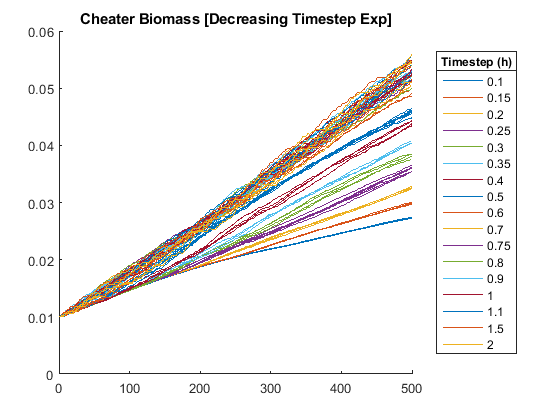


figure();
hold on;
lastts = 0;
for i = 1:nrows
    row = rd(i,:);
    coloridx = find(timesteps == row.ts(1));
    visibility = 'off';
    if coloridx > lastts
        lastts = coloridx;
        visibility = 'on';
    end
    r = row.biomass_cheater{1};
    plot(row.t{1},r,'color',colors(coloridx,:),'HandleVisibility',visibility);
end
title('Cheater Biomass [Decreasing Timestep Exp]');
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep (h)');
hold off;

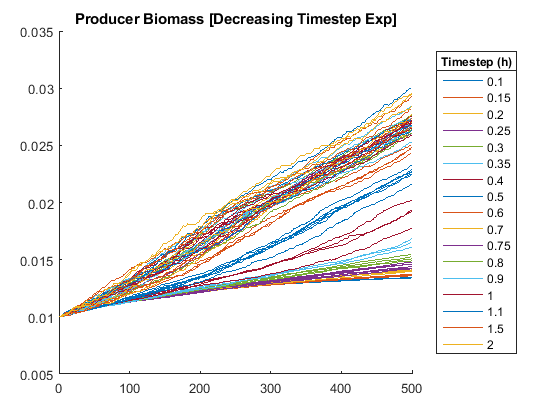


figure();
hold on;
lastts = 0;
for i = 1:nrows
    row = rd(i,:);
    coloridx = find(timesteps == row.ts(1));
    r = row.biomass_producer{1};
    visibility = 'off';
    if coloridx > lastts
        lastts = coloridx;
        visibility = 'on';
    end
    plot(row.t{1},r,'color',colors(coloridx,:),'HandleVisibility',visibility);
end
title('Producer Biomass [Decreasing Timestep Exp]');
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep (h)');
hold off;

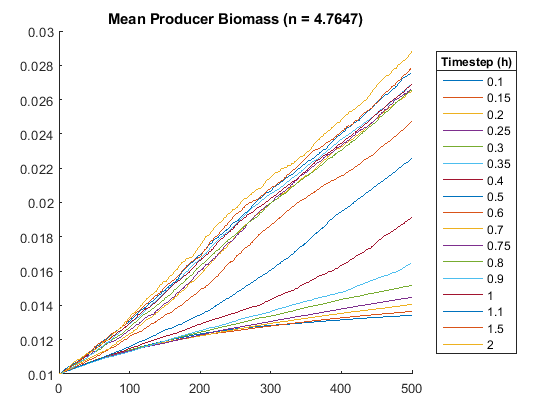

%Use the means of each series
legendstr = arrayfun(@(x) num2str(x),timesteps,'uniformoutput',false);
meandat = table();
meandat.t = cell(length(timesteps),1);
meandat.producer = cell(length(timesteps),1);
meandat.cheater = cell(length(timesteps),1);
meandat.ratio1 = cell(length(timesteps),1);
meandat.ratio2 = cell(length(timesteps),1);
meandat.total = cell(length(timesteps),1);
for i = 1:length(timesteps)
    d = rd(rd.ts == timesteps(i),:);
    meandat.t{i} = d.t{1};
    producer = horzcat(d.biomass_producer{:});
    meandat.producer{i} = mean(producer,2);
    cheater = horzcat(d.biomass_cheater{:});
    meandat.cheater{i} = mean(cheater,2);
    r1 = cheater ./ producer;
    meandat.ratio1{i} = mean(r1,2);
    r2 = cheater ./ producer;
    meandat.ratio2{i} = mean(r2,2);
    meandat.total{i} = mean(cheater + producer,2);
    meandat.producer_sd{i} = std(producer')';
    meandat.cheater_sd{i} = std(cheater')';
    meandat.ratio_sd{i} = std(r1')';
    meandat.total_sd{i} = std(cheater' + producer')';
end
[totalrows,totalcols] = size(rd);
n = totalrows / length(timesteps);
nstr = num2str(n);
figure();
hold on;
for i = 1:length(timesteps)
    plot(meandat.t{i},meandat.producer{i},'color',colors(i,:));
end
title(['Mean Producer Biomass (n = ' nstr ')']);
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep (h)');
hold off;

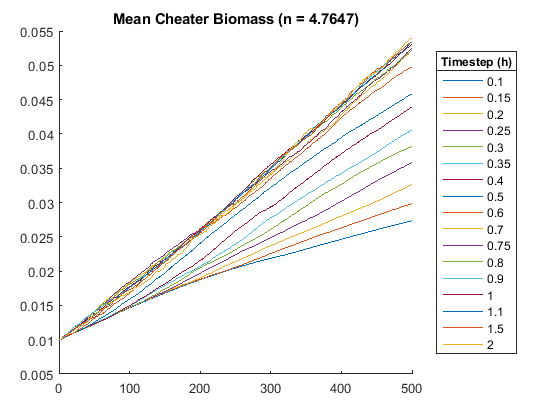


figure();
hold on;
for i = 1:length(timesteps)
    plot(meandat.t{i},meandat.cheater{i},'color',colors(i,:));
end
title(['Mean Cheater Biomass (n = ' nstr ')']);
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep (h)');
hold off;

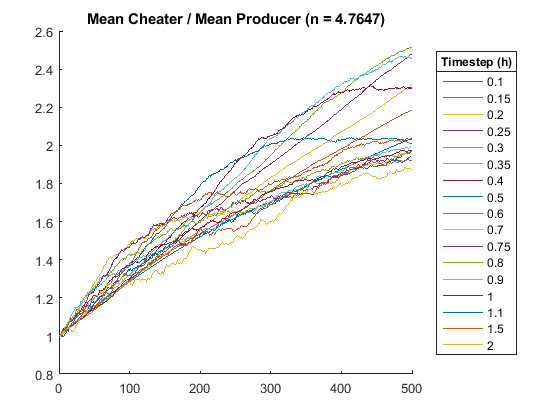


figure();
hold on;
for i = 1:length(timesteps)
    plot(meandat.t{i},meandat.ratio1{i},'color',colors(i,:));
end
title(['Mean Cheater / Mean Producer (n = ' nstr ')']);
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep (h)');
hold off;

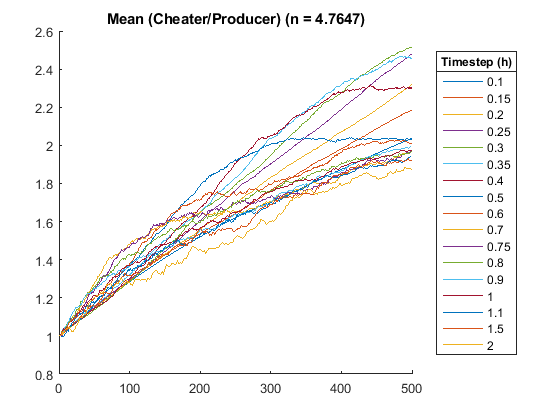


figure();
hold on;
for i = 1:length(timesteps)
    plot(meandat.t{i},meandat.ratio2{i},'color',colors(i,:));
end
title(['Mean (Cheater/Producer) (n = ' nstr ')']);
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep (h)');
hold off;

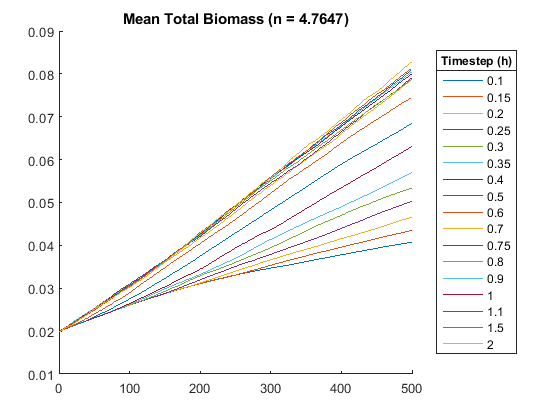


figure();
hold on;
for i = 1:length(timesteps)
    plot(meandat.t{i},meandat.total{i},'color',colors(i,:));
end
title(['Mean Total Biomass (n = ' nstr ')']);
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep (h)');
hold off;

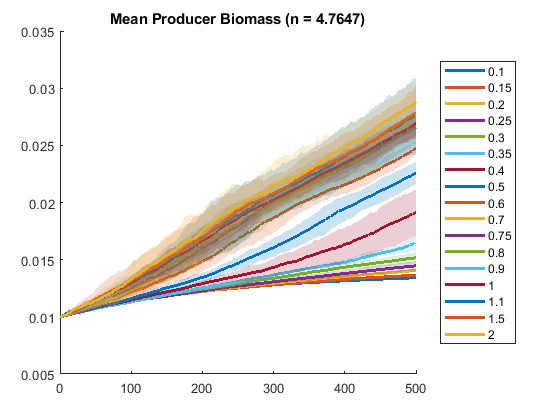

%Plots with confidence intervals
figure();
hold on;
for i = 1:length(timesteps)
    series = meandat.producer{i};
    sd = meandat.producer_sd{i};
    plot(meandat.t{i},series,'color',colors(i,:),'linewidth',2);
    xedge = [meandat.t{i}; flip(meandat.t{i})];
    y_down = series - (1.96 *sd);
    y_up = series + (1.96 * sd);
    yedge = [y_down; flip(y_up)];
    fill(xedge,yedge,colors(i,:),'FaceAlpha',0.2,'EdgeColor','none','HandleVisibility','off');
end
title(['Mean Producer Biomass (n = ' nstr ')']);
legend(legendstr,'location','eastoutside');
hold off;

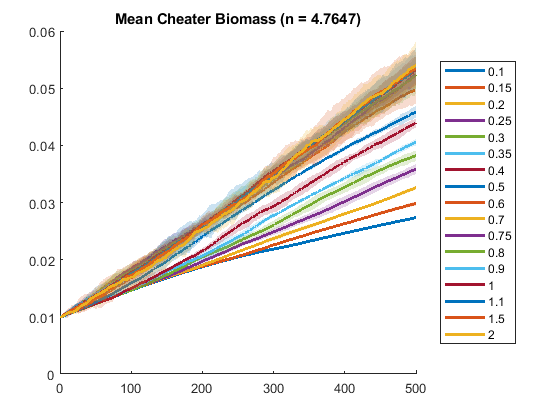


figure();
hold on;
for i = 1:length(timesteps)
    series = meandat.cheater{i};
    sd = meandat.cheater_sd{i};
    plot(meandat.t{i},series,'color',colors(i,:),'linewidth',2);
    xedge = [meandat.t{i}; flip(meandat.t{i})];
    y_down = series - (1.96 *sd);
    y_up = series + (1.96 * sd);
    yedge = [y_down; flip(y_up)];
    fill(xedge,yedge,colors(i,:),'FaceAlpha',0.2,'EdgeColor','none','HandleVisibility','off');
end
title(['Mean Cheater Biomass (n = ' nstr ')']);
legend(legendstr,'location','eastoutside');
hold off;

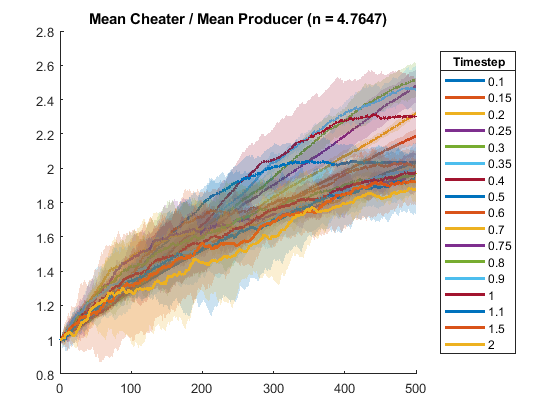


figure();
hold on;
for i = 1:length(timesteps)
    series = meandat.ratio1{i};
    sd = meandat.ratio_sd{i};
    plot(meandat.t{i},series,'color',colors(i,:),'linewidth',2);
    xedge = [meandat.t{i}; flip(meandat.t{i})];
    y_down = series - (1.96 *sd);
    y_up = series + (1.96 * sd);
    yedge = [y_down; flip(y_up)];
    fill(xedge,yedge,colors(i,:),'FaceAlpha',0.2,'EdgeColor','none','HandleVisibility','off');
end
title(['Mean Cheater / Mean Producer (n = ' nstr ')']);
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep');
hold off;

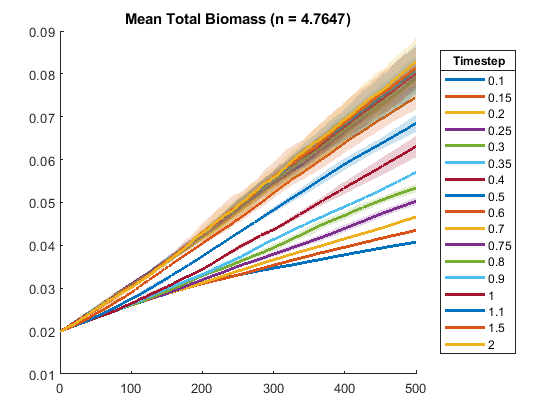


figure();
hold on;
for i = 1:length(timesteps)
    series = meandat.total{i};
    sd = meandat.total_sd{i};
    plot(meandat.t{i},series,'color',colors(i,:),'linewidth',2);
    xedge = [meandat.t{i}; flip(meandat.t{i})];
    y_down = series - (1.96 *sd);
    y_up = series + (1.96 * sd);
    yedge = [y_down; flip(y_up)];
    fill(xedge,yedge,colors(i,:),'FaceAlpha',0.2,'EdgeColor','none','HandleVisibility','off');
end
title(['Mean Total Biomass (n = ' nstr ')']);
leg = legend(legendstr,'location','eastoutside');
title(leg,'Timestep');
hold off;

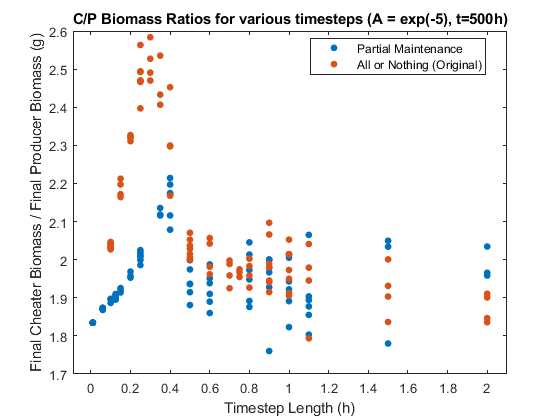

%Scatter plot of final ratios over different timestep lengths
timesteps = unique(randdat.ts);
colors = lines(2);
cheaterends = cellfun(@(x) x(end),randdat.biomass_cheater);
producerends = cellfun(@(x) x(end),randdat.biomass_producer);
labels = {'All or Nothing (Original)' 'Partial Maintenance'};
group = labels(randdat.maint_replaced+1)';
gscatter(randdat.ts,cheaterends ./ producerends,group,colors);
title('C/P Biomass Ratios for various timesteps (A = exp(-5), t=500h)');
ylabel('Final Cheater Biomass / Final Producer Biomass (g)');
xlabel('Timestep Length (h)');

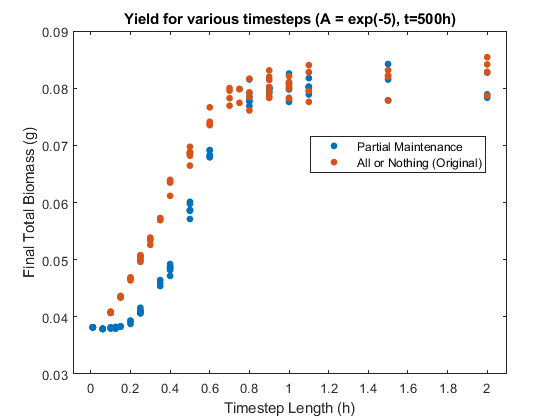


gscatter(randdat.ts,cheaterends + producerends,group,colors);
title('Yield for various timesteps (A = exp(-5), t=500h)');
ylabel('Final Total Biomass (g)');
xlabel('Timestep Length (h)');

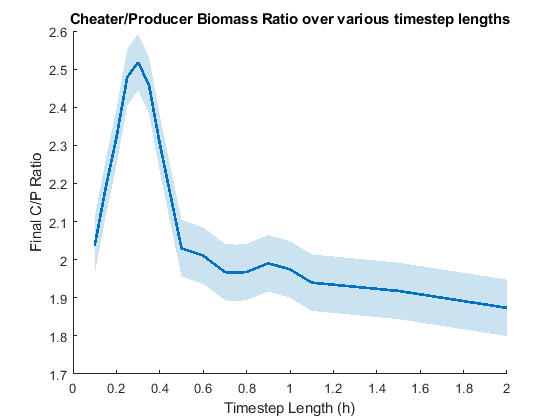

%Plot the data with standard dev for the *normal maintenance method*
orig = randdat(~randdat.maint_replaced,:);
timesteps = unique(orig.ts);
origmeans = [];
for i = 1:length(timesteps)
    subtab = orig(orig.ts == timesteps(i),:);
    cheaterends = cellfun(@(x) x(end),subtab.biomass_cheater);
    producerends = cellfun(@(x) x(end),subtab.biomass_producer);
    origratios(i) = mean(cheaterends ./ producerends);
    origtotal(i) = mean(cheaterends + producerends);
    origratiosd = std(cheaterends ./ producerends);
    origtotalsd = std(cheaterends + producerends);
end

figure();
hold on;
plot(timesteps,origratios,'linewidth',2);
xedge = [timesteps; flip(timesteps)];
y_down = origratios - (1.96 *origratiosd);
y_up = origratios + (1.96 * origratiosd);
yedge = [y_down, flip(y_up)];
fill(xedge,yedge,colors(1,:),'FaceAlpha',0.2,'EdgeColor','none','HandleVisibility','off');
hold off;
title('Cheater/Producer Biomass Ratio over various timestep lengths');
xlabel ('Timestep Length (h)');
ylabel('Final C/P Ratio');

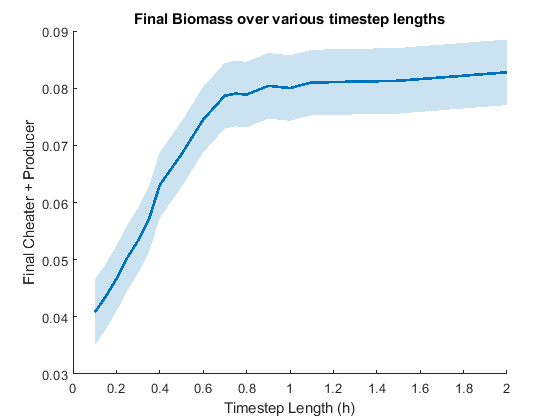

figure;
hold on;
plot(timesteps,origtotal,'linewidth',2);
xedge = [timesteps; flip(timesteps)];
y_down = origtotal - (1.96 *origtotalsd);
y_up = origtotal + (1.96 * origtotalsd);
yedge = [y_down, flip(y_up)];
fill(xedge,yedge,colors(1,:),'FaceAlpha',0.2,'EdgeColor','none','HandleVisibility','off');
title('Final Biomass over various timestep lengths');
xlabel ('Timestep Length (h)');
ylabel('Final Cheater + Producer');
hold off;

%Plot the data with standard dev for the *PARTIAL maintenance method*
part = randdat(~randdat.maint_replaced,:);
timesteps = unique(part.ts);
partmeans = [];
for i = 1:length(timesteps)
    subtab = part(part.ts == timesteps(i),:);
    cheaterends = cellfun(@(x) x(end),subtab.biomass_cheater);
    producerends = cellfun(@(x) x(end),subtab.biomass_producer);
    partratios(i) = mean(cheaterends ./ producerends);
    parttotal(i) = mean(cheaterends + producerends);
    partratiosd = std(cheaterends ./ producerends);
    parttotalsd = std(cheaterends + producerends);
end

figure();
hold on;
plot(timesteps,partratios,'linewidth',2);
xedge = [timesteps; flip(timesteps)];
y_down = partratios - (1.96 *partratiosd);
y_up = partratios + (1.96 * partratiosd);
yedge = [y_down, flip(y_up)];
fill(xedge,yedge,colors(1,:),'FaceAlpha',0.2,'EdgeColor','none','HandleVisibility','off');
hold off;
title('Cheater/Producer Biomass Ratio over various timestep lengths');
xlabel ('Timestep Length (h)');
ylabel('Final C/P Ratio');

figure;
hold on;
plot(timesteps,parttotal,'linewidth',2);
xedge = [timesteps; flip(timesteps)];
y_down = parttotal - (1.96 *parttotalsd);
y_up = parttotal + (1.96 * parttotalsd);
yedge = [y_down, flip(y_up)];
fill(xedge,yedge,colors(1,:),'FaceAlpha',0.2,'EdgeColor','none','HandleVisibility','off');
title('Final Biomass over various timestep lengths');
xlabel ('Timestep Length (h)');
ylabel('Final Cheater + Producer');
hold off;